### Tilt + Offset Analysis

%% MOMENT MARGIN ANALYSIS (mechanism mounting check)
g_tip = 9.81; % m/s^2
g = g_tip;
in2m = 0.0254;

% Tilt Bound Definitions
ft2m = 0.3048;
abv_length = 1.125 * ft2m;  abv_width = 1.125 * ft2m;
m_payload = linspace(0, 10, 21);
radial_offset = 0.10;  angular_offset = deg2rad(4);
r_mech_mount = abv_length/2;

% Measured data points
arm_in = [28, 26]; % in
mass_g = [965, 1695]; % g

arm_m = arm_in * in2m; % m
mass_kg = mass_g / 1000; % kg
weight_N = mass_kg * g; % N

M_Nm    = weight_N .* arm_m; % N*m

M_crit_perp = M_Nm(1);
M_crit_tank = M_Nm(2);
 
M_crit_used = M_crit_tank;
 
% Sweep: mechanism mass (0-10 kg, SYS.03) x mounting arm
m_mech_sweep   = linspace(0, 10, 21);
arm_mech_sweep = [0.10, 0.15, 0.20, 0.25];
 
n_arms = length(arm_mech_sweep);
n_mass = length(m_mech_sweep);
 
M_applied    = zeros(n_arms, n_mass);
moment_ratio = zeros(n_arms, n_mass);
grounds_out  = false(n_arms, n_mass);
 
for a = 1:n_arms
    r = arm_mech_sweep(a);
    for i = 1:n_mass
        m = m_mech_sweep(i);
        M_applied(a,i)    = m * g_tip * r;
        moment_ratio(a,i) = M_applied(a,i) / M_crit_used;
        grounds_out(a,i)  = moment_ratio(a,i) >= 1;
    end
end
 
fprintf('\n TILT + OFFSET ANALYSIS (at 10 kg) \n');


 TILT + OFFSET ANALYSIS (at 10 kg) 


fprintf('%10s %12s %12s %14s\n', 'Arm(m)', 'M_app(N*m)', 'Ratio', 'Grounds out?');

    Arm(m)   M_app(N*m)        Ratio   Grounds out?


for a = 1:n_arms
    if grounds_out(a,end)
        groundsStr = 'yes';
    else
        groundsStr = 'no';
    end
    fprintf('%10.2f %12.3f %12.3f %14s\n', ...
        arm_mech_sweep(a), M_applied(a,end), moment_ratio(a,end), groundsStr);
end

      0.10        9.810        0.893             no
      0.15       14.715        1.340            yes
      0.20       19.620        1.787            yes
      0.25       24.525        2.233            yes


fprintf('=====================================================================\n');

if M_crit_used == M_crit_perp
    sideStr = 'perpendicular/weaker';
else
    sideStr = 'tank/stronger';
end
fprintf('Critical moment used: %.2f N*m (%s side)\n', M_crit_used, sideStr);

Critical moment used: 10.98 N*m (tank/stronger side)


 
% Max safe mounting arm at 10 kg (direct from M = m*g*r => r = M/(m*g))
max_safe_arm_at_10kg = M_crit_used / (10 * g_tip);
fprintf('At 10 kg payload, max mounting arm before exceeding M_crit: %.3f m\n\n', ...
    max_safe_arm_at_10kg);

At 10 kg payload, max mounting arm before exceeding M_crit: 0.112 m



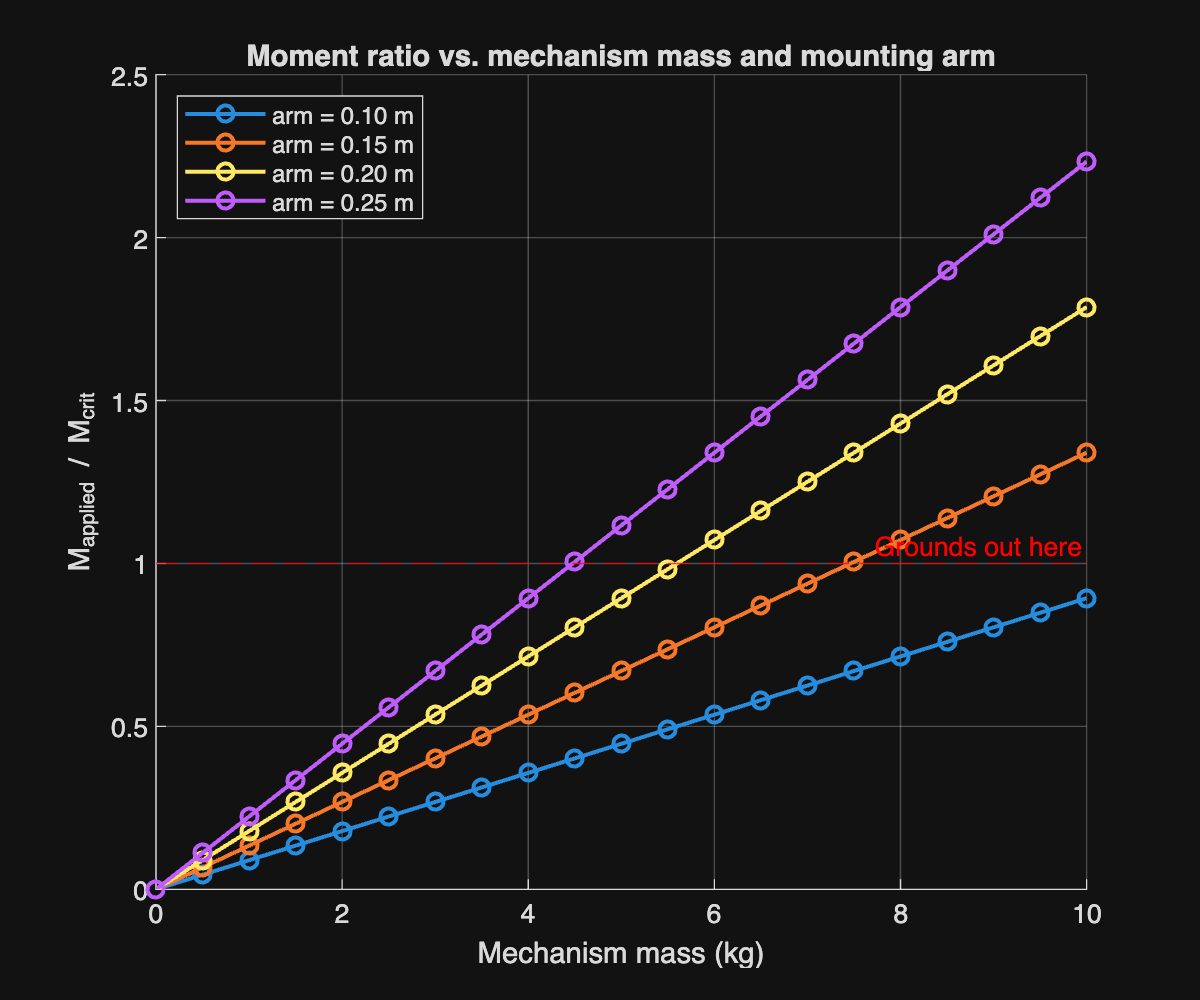

 
%% Plot: moment ratio vs. mass
 
figure('Name', 'Moment Margin Analysis', 'Position', [650 100 600 500]);
 
hold on;
for a = 1:n_arms
    plot(m_mech_sweep, moment_ratio(a,:), '-o', 'LineWidth', 1.5, ...
        'DisplayName', sprintf('arm = %.2f m', arm_mech_sweep(a)));
end
yline(1, 'r--', 'Grounds out here', 'HandleVisibility', 'off');
xlabel('Mechanism mass (kg)'); ylabel('M_{applied} / M_{crit}');
title('Moment ratio vs. mechanism mass and mounting arm');
legend('Location', 'northwest'); grid on;


in2m = 0.0254; g0 = 9.81;

gap_value = 0.006;
gap_units = 'in';
pad_half_spacing = abv_width/2;
h_interface = 0.30;

if strcmpi(gap_units, 'in'), gap_m = gap_value*in2m; else, gap_m = gap_value*1e-3; end
theta_max = atan(gap_m / pad_half_spacing);           % rad
induced_offset = h_interface * sin(theta_max);         % m

fprintf('\n TILT BOUND (item 7) \n');


 TILT BOUND (item 7) 


fprintf('Float height %.4g %s (%.0f um), pad half-spacing %.3f m\n', gap_value, gap_units, gap_m*1e6, pad_half_spacing);

Float height 0.006 in (152 um), pad half-spacing 0.171 m


fprintf('Max tilt before grounding: %.4f deg (%.2f%% of SYS.08 4 deg)\n', rad2deg(theta_max), 100*theta_max/angular_offset);

Max tilt before grounding: 0.0509 deg (1.27% of SYS.08 4 deg)


fprintf('Max capture-point shift:   %.3f mm (%.3f%% of SYS.07 %.2f m)\n', induced_offset*1e3, 100*induced_offset/radial_offset, radial_offset);

Max capture-point shift:   0.267 mm (0.267% of SYS.07 0.10 m)



% ARL tipping test (critical moment = mass hung at arm that grounded the ABV)
arm_tip  = [28 26] * in2m;
mass_tip = [965 1695] / 1000;
M_crit   = mass_tip * g0 .* arm_tip;
M_used   = M_crit(2);

M_applied = m_payload * g0 * r_mech_mount;     % N*m
moment_ratio = M_applied / M_used;
m_max_mount  = M_used / (g0 * r_mech_mount);   % kg
r_max_10kg   = M_used / (g0 * 10);             % m

fprintf('Critical moment: %.2f N*m (perpendicular), %.2f N*m (tank side)\n', M_crit(1), M_crit(2));

Critical moment: 6.73 N*m (perpendicular), 10.98 N*m (tank side)


fprintf('Mechanism at %.3f m: grounds out above %.2f kg\n', r_mech_mount, m_max_mount);

Mechanism at 0.171 m: grounds out above 6.53 kg


fprintf('A 10 kg mechanism must sit within %.3f m of ABV center\n', r_max_10kg);

A 10 kg mechanism must sit within 0.112 m of ABV center


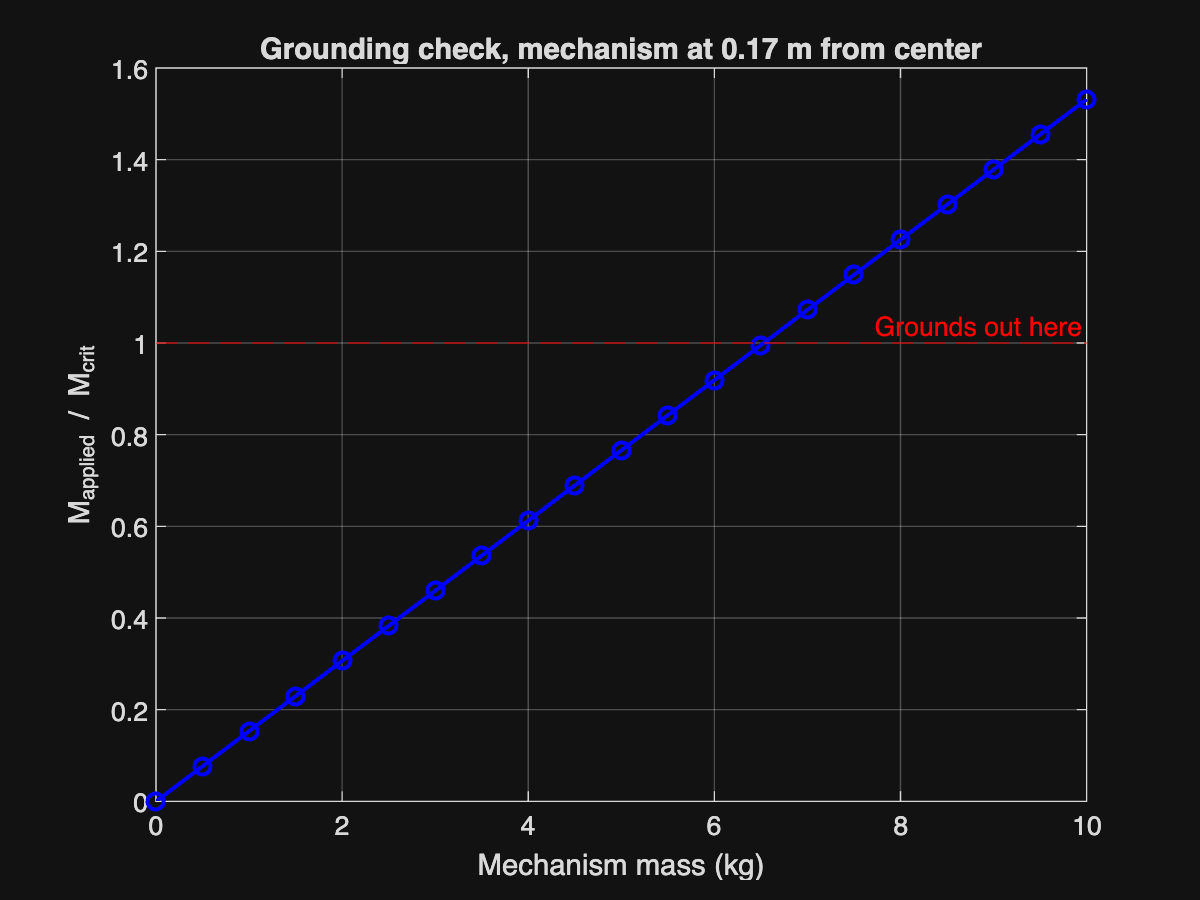


figure('Name', 'Tilt and Grounding', 'Position', [150 150 600 450]);
plot(m_payload, moment_ratio, 'b-o', 'LineWidth', 1.5); hold on;
yline(1, 'r--', 'Grounds out here', 'HandleVisibility', 'off');xlabel('Mechanism mass (kg)'); ylabel('M_{applied} / M_{crit}');
title(sprintf('Grounding check, mechanism at %.2f m from center', r_mech_mount)); grid on;